# Chap 21 Prob 36

Solve Chapter 21 Problem 36.

The parameter values are specified below. Any consistent units are valid.

clear
m = 2; % mass
k = 72; % spring constant
c = 8; % damping constant
x0 = 1; % initial position
v0 = 0; % initial velocity
t0 = 0; % initial time
tf = 1; % final time
ntime = 1001; % number of time points

## Step 8: Solve the EOM, Solve the Problem

### Numerical Solution

[T S] = ode45(@(t,s)eom(t,s,m,k,c),linspace(t0,tf,ntime),[x0,v0]);

### Analytical Solution

omegan = sqrt(k/m)

omegan = 6

zeta = c/(2*m*omegan)

zeta = 0.3333

if zeta<1
    fprintf('zeta < 1, underdamped system')
    omegad = omegan*sqrt(1-zeta^2)
    A = (v0+zeta*omegan*x0)/omegad
    B = x0
    x = exp(-zeta*omegan*T).*(A*sin(omegad*T)+B*cos(omegad*T));
elseif zeta>1
    fprintf('zeta > 1, overdamped system')
    lambda1 = -zeta*omegan+omegan*sqrt(zeta^2-1)
    lambda2 = -zeta*omegan-omegan*sqrt(zeta^2-1)
    A = (lambda2*x0-v0)/(lambda2-lambda1)
    B = (-lambda1*x0+v0)/(lambda2-lambda1)
    x = A*exp(lambda1*T)+B*exp(lambda2*T);
elseif zeta==1
    fprintf('zeta = 1, critically damped system')
    A = x0
    B = v0+omegan*x0
    x = (A+B*T).*exp(-omegan*T);
end

zeta < 1, underdamped system

omegad = 5.6569

A = 0.3536

B = 1

### Post-Process and Interpret Results

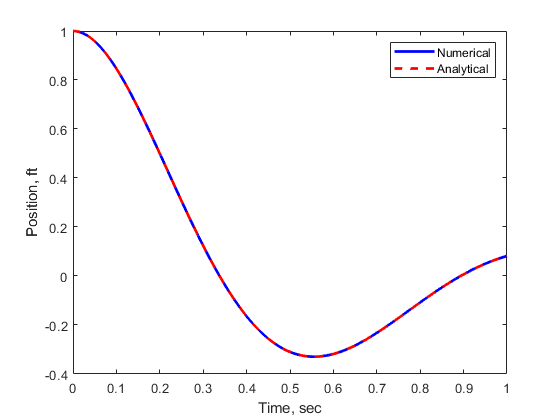

plot(T,S(:,1),'-b',T,x,'--r','linewidth',2)
xlabel('Time, sec')
ylabel('Position, ft')
legend('Numerical','Analytical','location','Northeast')

fprintf('Numerical solution for final position is %6.3f ft/s \n',S(end,1))

Numerical solution for final position is  0.082 ft/s 


fprintf('Analytical solution for final position is %6.3f ft/s \n',x(end))

Analytical solution for final position is  0.082 ft/s 


function sdot = eom(t,s,m,k,c)
sdot(1,1) = s(2);
sdot(2,1) = 1/m*(-c*s(2)-k*s(1));
end